# Expand Example 3.46:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Consider the periodic pulse train with period of $T_{0}=20$ ms and duty cycle $d=0.2$ shown in the figure:

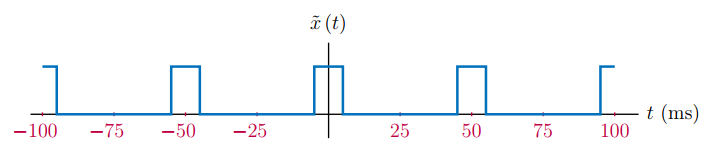

Compute its EFS coefficients:

T0 = 0.05;     % Period of pulse train  
f0 = 1/T0;     % Fundamental frequency
k = [-20:20];  % Vector of harmonic indices
c = 0.2*sinc(0.2*k);  % EFS coefficients

Let this signal be applied to a first-order RC circuit with 3-dB cutoff frequency of $f_{c}$.  The system function for the RC circuit is

        
$$H(f)=\frac{1}{1+j(f/f_{c})$$


The EFS coefficients of the output signal $y(t)$ are computed as

        
$$d_{k}=c_{k}\,H(k f_{0})=\frac{c_{k}}{1+j(k f_{0}/f_{c})}$$


fc = 80;  % 3-dB cutoff frequency
% Define an anonymous function for H(f)
H = @(f) 1./(1+j*f/fc);
% Compute the EFS coefficients for the output signal
d = c.*H(k*f0);
f = k*f0;  % Integer multiples of the fundamental frequency

Graph the system function as well as the EFS spectra for input and output signals.

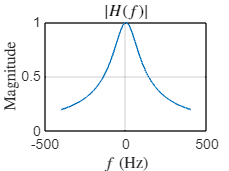

plot(f,abs(H(f))); grid;
set(0,'defaultTextInterpreter','latex');
xlabel('$f$ (Hz)');
ylabel('Magnitude');
title('$|H(f)|$');

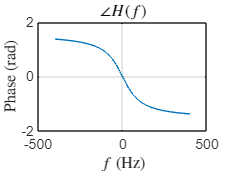

plot(f,angle(H(f))); grid;
xlabel('$f$ (Hz)');
ylabel('Phase (rad)');
title('$\angle H(f)$');

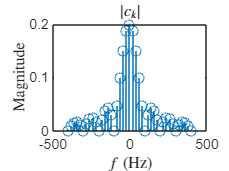

stem(f,abs(c));
xlabel('$f$ (Hz)');
ylabel('Magnitude');
title('$|c_{k}|$');

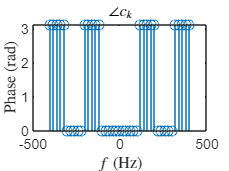

stem(f,angle(c));
xlabel('$f$ (Hz)');
ylabel('Phase (rad)');
title('$\angle c_{k}$');

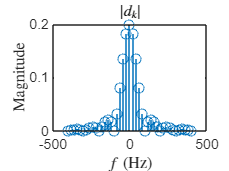

stem(f,abs(d));
xlabel('$f$ (Hz)');
ylabel('Magnitude');
title('$|d_{k}|$');

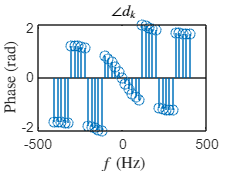

stem(f,angle(d));
xlabel('$f$ (Hz)');
ylabel('Phase (rad)');
title('$\angle d_{k}$');

Compute and graph finite-harmonic approximation to the output signal $y(t)$.

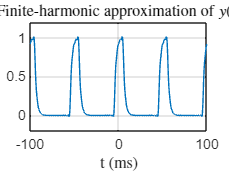

t = [-100:0.2:100];  % Time instants in milliseconds.
yhat = zeros(size(t));
for kk=-20:20,
  yhat = yhat+d(kk+21)*exp(j*2*pi*kk*f0*t/1000);
end;
yhat = real(yhat);  % Remove residual imaginary parts due to roundoff error
plot(t,yhat); grid;
axis([-100,100,-0.2,1.2]);
xlabel('t (ms)');
title('Finite-harmonic approximation of $y(t)$');

set(0,'defaultTextInterpreter','tex');